clear
% MESHING OF STRUCTURE
% Approx number of elements
N = 5100; % 40 390
% Compute mesh
[Nodes_Global,Pos_Global,Ele_Nodes,Cl1,Cl2,sideB,A2] = meshing(N);

el_sidex = 0.0013

el_sidex = 0.0013

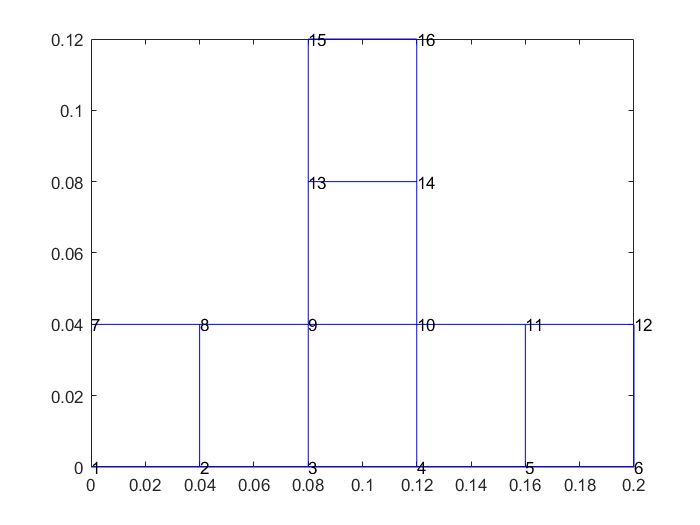


% PLOT UNDEFORMED SHAPE
% Close lines
Cl = [Cl2;Cl1];
% Figure plot
figure
for ele = 1:size(Ele_Nodes,2)/2
    plot(Ele_Nodes(:,ele*2-1),Ele_Nodes(:,ele*2),'b-')
    %text(Ele_Nodes(1,ele*2-1),Ele_Nodes(1,ele*2),num2str(ele))
    hold on
end
plot(Cl(:,1),Cl(:,2),'b-')
% Plot nodes text
N = Nodes_Global';
N = N(:);
N = N';
for ele = 1:size(Nodes_Global,1)
    text(N(1,ele*2-1),N(1,ele*2),num2str(ele))
    hold on
end

%set(gca, 'YDir','reverse')

% Force vector
fa = 5000; % Newtons
t = 0.0025; %m
fy_edge = fa*t*sideB/2;
fy_in = fa*t*sideB;
S = size(Nodes_Global,1)*2;
f = zeros(1,S);
nodes_f = A2+1;
for i = S:-2:1+S-nodes_f*2
    
    if i == 2+S-nodes_f*2
        f(i) = fy_edge;
    elseif i == S
        f(i) = fy_edge;
    else
        f(i) = fy_in;
    end
    
end

f2 = fVec(sideB,S,A2);

% DISPLACEMENT VECTOR
left_C = ismember(Nodes_Global(:,1),0);
idx1 = find(left_C);
right_C = ismember(Nodes_Global(:,1),0.2);
idx2 = find(right_C);
zero_disp_nodes = [idx1;idx2];
zero_disp_nodes = [zero_disp_nodes*2-1;zero_disp_nodes*2]

zero_disp_nodes =      1
    13
    11
    23
     2
    14
    12
    24


n = 16;
FX=sym('dx',[1,n]);
FY=sym('dy',[1,n]);
val = 1:1:n;

counter = 1;
for i = 1:n
    F(counter) = FX(i);
    counter = counter + 1;
    F(counter) = FY(i);
    counter = counter + 1;
end
counter = 1;
for i = 1:n
    node_val(counter) = val(i);
    counter = counter + 1;
    node_val(counter) = val(i);
    counter = counter + 1;
end
F(zero_disp_nodes) = [];
node_val(zero_disp_nodes) = [];

test = node_val(:);
test2 = reshape(test,[2,12])'

test2 =      2     2
     3     3
     4     4
     5     5
     8     8
     9     9
    10    10
    11    11
    13    13
    14    14


test3(test2(:,1),1:2) = test2 

test3 =      0     0
     2     2
     3     3
     4     4
     5     5
     0     0
     0     0
     8     8
     9     9
    10    10


% Strain Interpolation
syms xi real
syms eta real
sh(1) = 1/4 * (1-xi)*(1-eta);
sh(2) = 1/4 * (1+xi)*(1-eta);
sh(3) = 1/4 * (1+xi)*(1+eta);
sh(4) = 1/4 * (1-xi)*(1+eta);

element = 6;
L = elLmat(element,Pos_Global,S);
disp = d_Comp';
disp = disp(:);
d1 = L*disp;
H = H_els{element};
strains = H*d1;

We know the boundaries in the parent coordinate system. So, we can form vector of values for $\xi$ and $\eta$:

xi_1 = -1:0.01:1;
eta_1 = -1:0.01:1;

With these values, we can map using the shape functions to obtain the vector of values in the physical coordinate system:

SIZE1 = size(xi_1,2);

xy_bar = Ele_Nodes(:,element*2-1:element*2);
x_coord = sh*(xy_bar(1:4,1));
y_coord = sh*(xy_bar(1:4,2));
for i = 1:SIZE1
    
    x(i) = subs(x_coord,[xi,eta],[xi_1(i),eta_1(i)]);
    y(i) = subs(y_coord,[xi,eta],[xi_1(i),eta_1(i)]);
    
end
x = double(x);
y = double(y);

Here, we will use two meshgrids. The first will be for the physical coordinate system and will be used in the plots. The second meshgrid will be for the parent coordinate system and will be used for the calculations of strain and displacement:

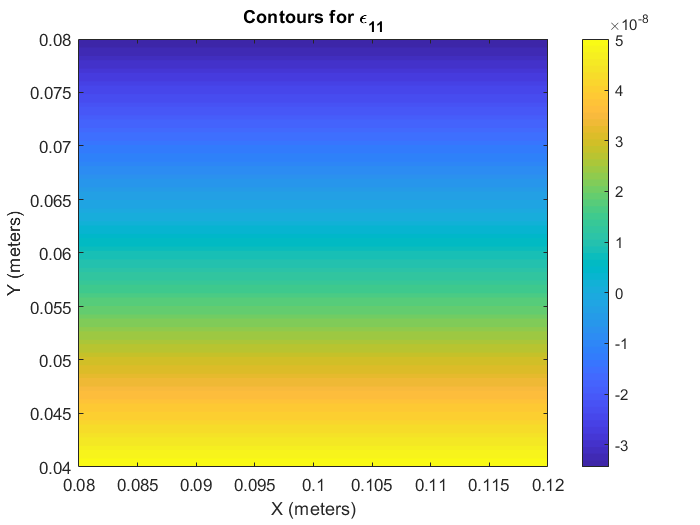

[xx,yy] = meshgrid(x,y);
[xi_2,eta_2] = meshgrid(xi_1,eta_1);
strain_xx = subs(strains(1),eta,eta_2);
Number = 100;
figure
contourf(xx,yy,strain_xx,Number,'LineColor','none')
colorbar
title('Contours for \epsilon_{11}')
xlabel('X (meters)')
ylabel('Y (meters)')

element = 6;
L = elLmat(element,Pos_Global,S);
H = H_els{element};
xy_bar = Ele_Nodes(:,element*2-1:element*2);
figure
strainPlot(L,d_Comp,H,xy_bar)

ans = 100

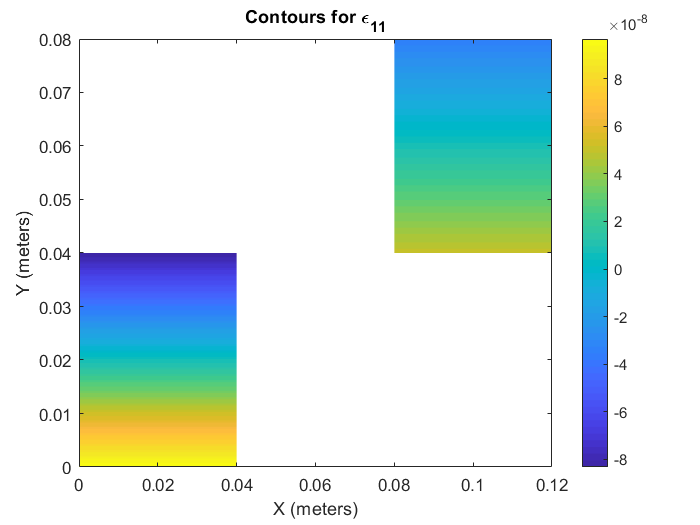

ans = 100

hold on
element = 1;
L = elLmat(element,Pos_Global,S);
H = H_els{element};
xy_bar = Ele_Nodes(:,element*2-1:element*2);
strainPlot(L,d_Comp,H,xy_bar)

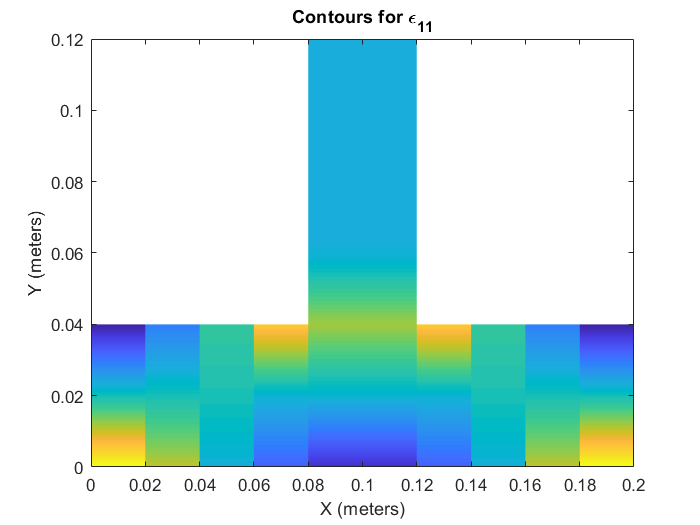

figure
for i = 1:size(Ele_Nodes,2)/2
    
    L = elLmat(i,Pos_Global,S);
    H = H_els{i};
    xy_bar = Ele_Nodes(:,i*2-1:i*2);
    strainPlot(L,d_Comp,H,xy_bar)
    hold on
    
end